# Model the Heat Tolerance of Components Exposed to Electronics

This finite element thermal analysis (FEA) examines the heat tolerance for a robotics component of a commercial youBot.

A single domain heat conduction analysis is performed on the nearest robotic component to the heat producing circuit board.  The analysis is then extended to perform a Design of Experiment analysis to model temperature as a function of thermal conductivity. 

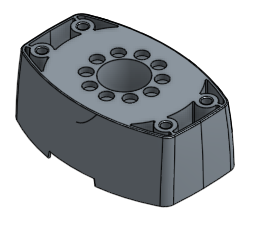     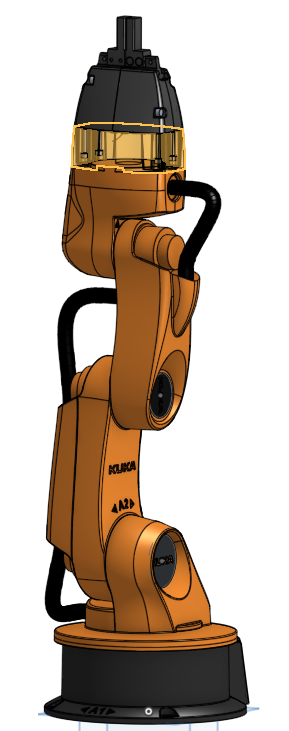      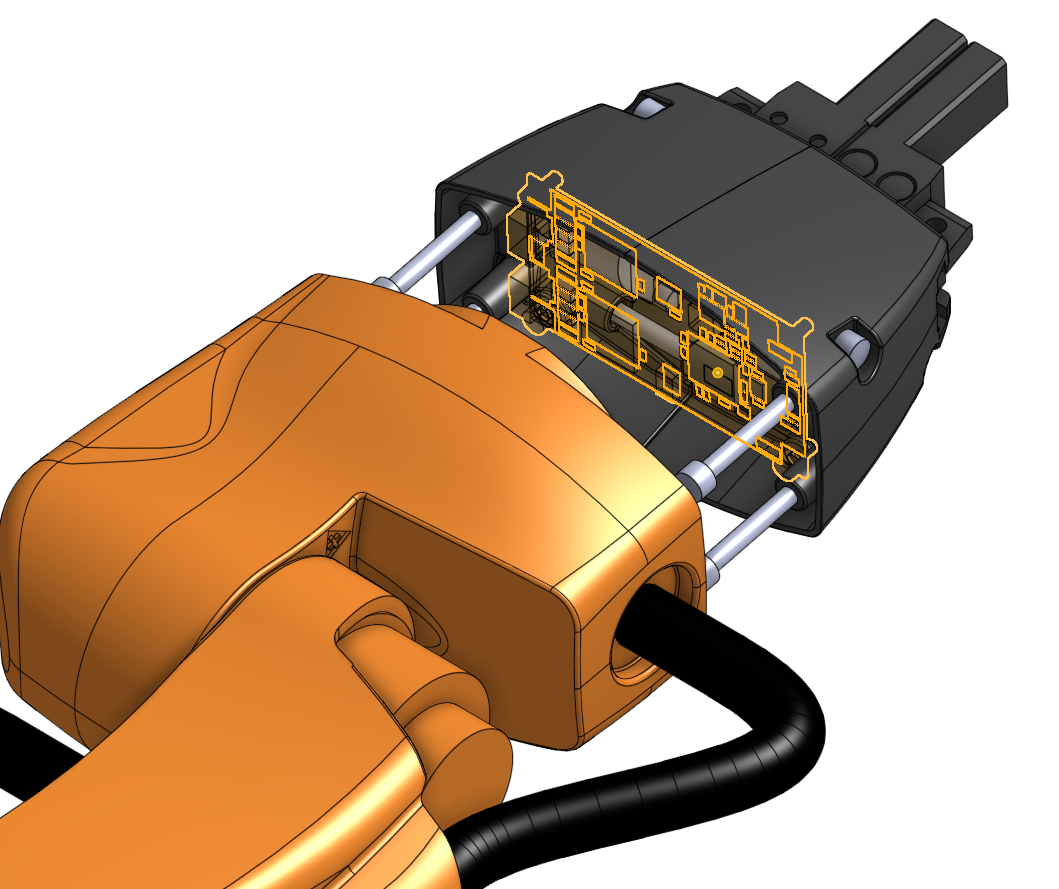

Figures : Gripper Pivot (left), youBot with pivot highlighted (middle) and circuit board (right)

Products used in this demo include

- **PDE Toolbox** for the finite element thermal analysis (FEA).  

- **Symbolic Math Toolbox** for unit conversions. 

- **Parallel Toolbox** for multiple analysis runs.

- **Statistics and Machine Learning Toolbox** for linear fitting. 

References : 

- What is a [youBot](http://www.youbot-store.com/)?

- Simscape Multibody [youBot simulation](https://www.mathworks.com/matlabcentral/fileexchange/61370-robot-arm-with-conveyor-belts).

This example requires **R2017a** or newer.

## Import the geometry

In the youBot the gripper pivot  sits underneath the electronics board and is exposed to the heat coming off the circut board. Here we will create the pde model, import the STL file of the gripper pivot, and plot it.

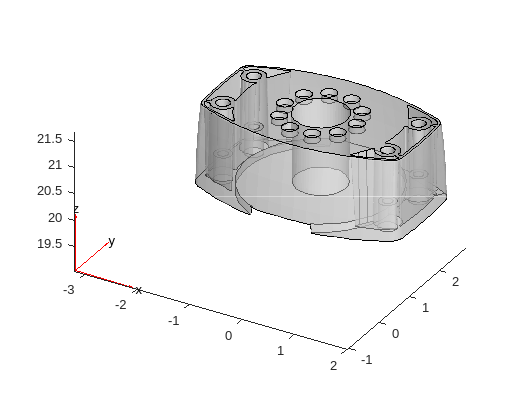

thermalmodel = createpde('thermal','steadystate');
importGeometry(thermalmodel,'Gripper Pivot.stl');
pdegplot(thermalmodel, 'FaceAlpha',0.5)

## Mesh the Geometry and Determine the Part size

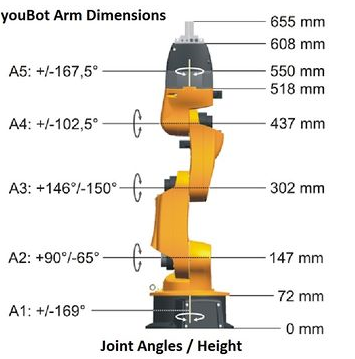                               

From the supplied dimensions above we can estimate the part height should be approximatly 32mm or 1.2598in.  However, we can see from the above `pdegplot` that the imported geometry is likely dimensioned in inches and not mm. Create and visualize a tetrahedral mesh of the component with a maximum value of 0.09 inches.

generateMesh(thermalmodel,'Hmax',.22);

ans =   FEMesh with properties:

             Nodes: [3x38080 double]
          Elements: [10x22274 double]
    MaxElementSize: 0.2022
    MinElementSize: 0.1011
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'


thermalmodel.Mesh

ans =   FEMesh with properties:

             Nodes: [3x38080 double]
          Elements: [10x22274 double]
    MaxElementSize: 0.2022
    MinElementSize: 0.1011
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'


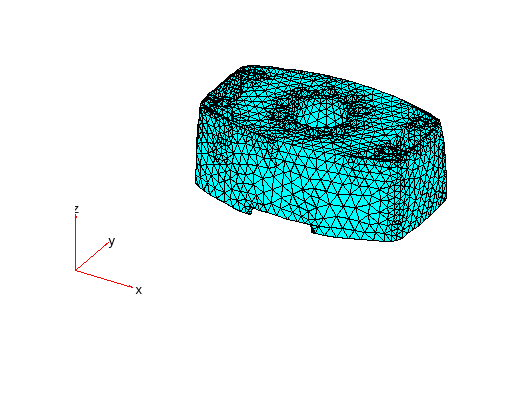

pdemesh(thermalmodel)

Measure the dimensions of the mesh. The part height is in fact 1.4606 inches.

xLength = max(thermalmodel.Mesh.Nodes(1,:)) - min(thermalmodel.Mesh.Nodes(1,:))

xLength = 4.0030

yLength = max(thermalmodel.Mesh.Nodes(2,:)) - min(thermalmodel.Mesh.Nodes(2,:))

yLength = 2.7170

zLength = max(thermalmodel.Mesh.Nodes(3,:)) - min(thermalmodel.Mesh.Nodes(3,:))

zLength = 1.4606

## Setup the Material Properties 

The material is assumed to be a magnesium alloy and to have a thermal conductivity of $52\;\frac{W}{m\;K}$. Material properties were taken from "Thermal Conductivity of Magnesium Alloys" [1].  Since the model is in inches we can use `symunit` to rewrite the value in inches. 

u = symunit;
tc = vpa(52) *u.Watt/(u.m*u.Kelvin)

$$tc = 52.0\,\frac{W}{K\,m}$$

tc = rewrite(tc,u.W/(u.in*u.Kelvin))

$$tc = 1.3208\,\frac{W}{K\,\mathrm{in}}$$

Now remove the units to obtain the value for the thermal properties. 

tc = double(separateUnits(tc));
thermalProperties(thermalmodel,'Cell',1,'ThermalConductivity',tc); 

## Set up the Boundary Conditions

The boundary conditions for this model are assumed, if more data was available we could improve the following assumptions.  

Unless overwritten, all of the side faces are set to have a natural convection coefficient of 25 $\frac{W}{m^2 K}$ representing heat transfer to an ambient air temperature of $288\ldotp 15K\;\left(25C^{\circ } \right)$.  Convert the convection coefficient to $\frac{W}{{\textrm{in}}^2 K}$ to be consistent with the model dimensions.

htc = vpa(25) *u.Watt/(u.m^2*u.Kelvin);
htc = rewrite(htc,u.Watt/(u.in^2*u.Kelvin));
htc = double(separateUnits(htc));
thermalBC(thermalmodel,'Face',1:thermalmodel.Geometry.NumFaces,'ConvectionCoefficient',htc,'AmbientTemperature',288.15);

The bottom face is given a fixed temperature assuming that the rest of the robotic arm acts as a heat sink.

thermalBC(thermalmodel,'Face',43,'Temperature',288.15);

The top face and inner hole is arbitrarily given a heat flux to represent the heat off the circuit board.  

thermalBC(thermalmodel,'Face',38,'HeatFlux',25);
thermalBC(thermalmodel,'Face',44,'HeatFlux',10);

## Solve the FEA analysis

Solve the model and calculate the max and bulk body temperatures. Time how long the solve takes.

tic
results = solve(thermalmodel);
time = toc

time = 1.1183

## Post-process the Results

Compute the max temperature in $K$ and rewrite that to $C^{\circ }$ or $F^{\circ }$ depending on your preference.

t_max = max(results.Temperature)

t_max = 312.9743

vpa(rewrite(t_max*u.Kelvin,u.Celsius,'Temperature','absolute'))

$$ans = 39.824325690319176374032394960523\,\mathrm{{}^{\circ}C}$$

vpa(rewrite(t_max*u.Kelvin,u.Fahrenheit,'Temperature','absolute'))

$$ans = 103.68378624257451747325831092894\,\mathrm{{}^{\circ}F}$$

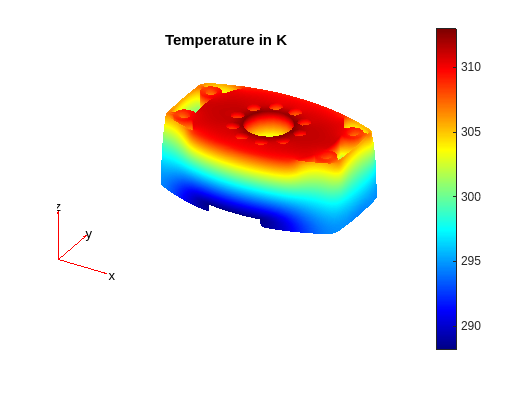

pdeplot3D(thermalmodel,'ColorMapData',results.Temperature)
title('Temperature in K')
colorbar

# Reference

- Lee, Ham, Kwon, Kim and Suh. "Thermal Conductivity of Magnesium Alloys". International Journal of Thermophysics. Jan 2012, 34-2343-2350. 

*Cop**yright MathWorks 2017*